## Module two project 11

%% Project 11: Wind Turbine Power Output (Mechanical / Energy)
clear; clc; close all;

%% -------------------------------------------------------------
% 1. Time-varying wind speed model
% -------------------------------------------------------------
t = 0:0.1:200;     % time (s)

% Sinusoidal wind speed variation (m/s)
V = 8 + 3*sin(0.05*t);  
% 8 m/s average wind, ±3 m/s fluctuation

%% -------------------------------------------------------------
% 2. Simplified turbine power equation
%    P = 0.5 * rho * A * Cp * V^3
% -------------------------------------------------------------
rho = 1.225;       % air density (kg/m^3)
R = 20;            % rotor radius (m)
A = pi*R^2;        % swept area (m^2)
Cp = 0.42;         % power coefficient (typical for modern turbines)

P = 0.5 * rho * A * Cp .* V.^3;   % instantaneous power (Watts)

%% -------------------------------------------------------------
% 3. Compute average power output
% -------------------------------------------------------------
P_avg = mean(P);

fprintf('Average power output: %.2f kW\n', P_avg/1000);

Average power output: 234.17 kW


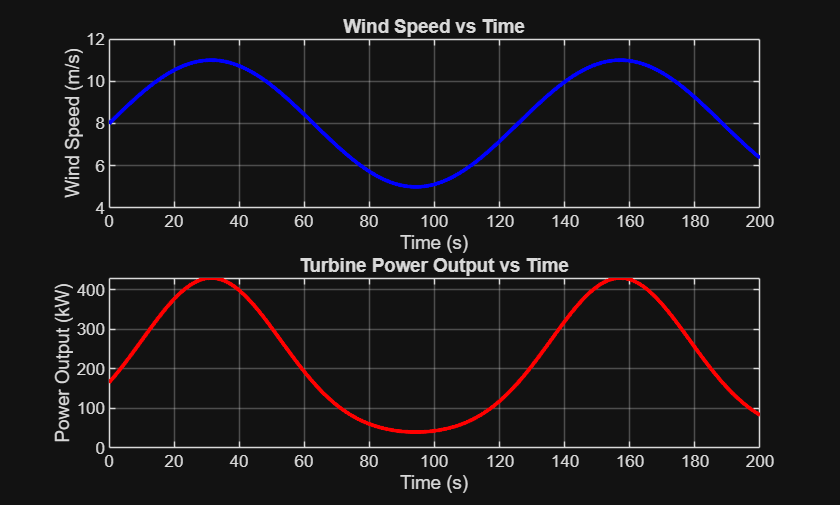


%% -------------------------------------------------------------
% 4. Plot wind speed and power output vs time
% -------------------------------------------------------------
figure;

subplot(2,1,1)
plot(t, V, 'b', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Wind Speed (m/s)');
title('Wind Speed vs Time');

subplot(2,1,2)
plot(t, P/1000, 'r', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Power Output (kW)');
title('Turbine Power Output vs Time');


%% -------------------------------------------------------------
% 5. Written discussion (printed to command window)
% -------------------------------------------------------------
fprintf('\nDiscussion:\n');


Discussion:


fprintf(['The wind speed varies sinusoidally, representing natural gusting behavior.\n' ...
         'Because turbine power scales with the cube of wind speed, even small\n' ...
         'increases in wind speed produce large increases in power output.\n' ...
         'The power curve therefore shows sharper peaks and deeper valleys than\n' ...
         'the wind speed curve. The average power output reflects the nonlinear\n' ...
         'relationship between wind variability and energy production.\n']);

The wind speed varies sinusoidally, representing natural gusting behavior.
Because turbine power scales with the cube of wind speed, even small
increases in wind speed produce large increases in power output.
The power curve therefore shows sharper peaks and deeper valleys than
the wind speed curve. The average power output reflects the nonlinear
relationship between wind variability and energy production.
